# Programmentwurf Simulationstechnik

Gruppe: Batuhan Aykut (6697882), Lars Annuth (1140146), Liza Thöne (9434335)

**Aufgabe 1:**

Ermitteln Sie den Verlauf für den Schwimmwinkel und die Giergeschwindigkeit für den Fall, dass Sie den Radlenkwinkel auf delta = 5° bei einer Geschwindigkeit von v = 18 m/s * springen lassen,

Verwenden Sie dafür folgende Parameter: m = 2000kg, J = 4000kgm², lv = 1.43m, lh = 1.4m, cv = 70000 N/rad , ch = 140000 N/rad

Berechnen Sie die Lösung mit Hilfe von Matlab. Stellen Sie die Ergebnisse grafisch dar, geben Sie die Winkel bzw. Winkelgeschwindigkeit in ° bzw. °/s an.

Parameter und deren Einheiten

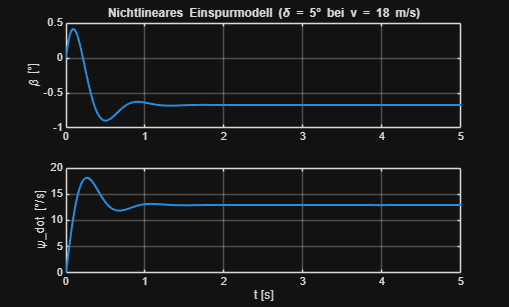

m = 2000;       % Masse [kg]
J = 4000;       % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]
v = 18;         % Fahrzeuggeschwindigkeit [m/s]

delta = deg2rad(5);   % Lenkwinkel [rad]

%% Simulation mit ode45
tspan = [0 5];
x0 = [0; 0];   % Anfangswerte: [beta0; psi_dot0]

odefun = @(t,x) bicycleNL(t,x,m,J,lv,lh,cv,ch,v,delta);
[t,x] = ode45(odefun, tspan, x0);

beta    = x(:,1);      % [rad]
psi_dot = x(:,2);      % [rad/s]

%% Umrechnung in Grad
beta_deg    = rad2deg(beta);
psi_dot_deg = rad2deg(psi_dot);

%% Plot
figure
subplot(2,1,1)
plot(t, beta_deg, 'LineWidth', 1.5)
grid on
ylabel('\beta [°]')
title('Nichtlineares Einspurmodell (\delta = 5° bei v = 18 m/s)')

subplot(2,1,2)
plot(t, psi_dot_deg, 'LineWidth', 1.5)
grid on
ylabel('\psi\_dot [°/s]')
xlabel('t [s]')


%% Nichtlineare Modellgleichungen
function dx = bicycleNL(~, x, m, J, lv, lh, cv, ch, v, delta)

    beta    = x(1);   % Schwimmwinkel [rad]
    psi_dot = x(2);   % Giergeschwindigkeit [rad/s]

    % Schutz gegen cos(beta) → 0
    cb = cos(beta);
    if abs(cb) < 1e-6
        cb = sign(cb)*1e-6;
    end

    % Schräglaufwinkel
    alpha_v = delta - (lv*psi_dot)/(v*cb) + tan(beta);
    alpha_h =        (lh*psi_dot)/(v*cb) - tan(beta);

    % Nichtlineare Differentialgleichungen
    beta_dot = -psi_dot + (1/(m*v)) * (cv*alpha_v + ch*alpha_h);
    psi_ddot = (1/J) * (lv*cv*alpha_v*cos(delta) - lh*ch*alpha_h);

    dx = [beta_dot; psi_ddot];
end

In Aufgabe 1 wird das Fahrverhalten eines Pkw mithilfe eines nichtlinearen Einspurmodells untersucht. Ziel der Aufgabe ist es, den zeitlichen Verlauf des Schwimmwinkels β sowie der Giergeschwindigkeit ψ̇ zu bestimmen, wenn der Radlenkwinkel δ bei einer konstanten Fahrzeuggeschwindigkeit von v = 18 m/s sprunghaft auf 5° gesetzt wird.

Zunächst werden alle gegebenen Fahrzeugparameter definiert. Der Lenkwinkel wird von Grad in Radiant umgerechnet, da MATLAB intern mit Bogenmaß rechnet.

Als Zustandsgrößen werden der Schwimmwinkel β und die Giergeschwindigkeit ψ̇ gewählt. Das System wird nicht linearisiert, sondern es werden die vollständigen nichtlinearen Bewegungsgleichungen verwendet. Die Nichtlinearität entsteht durch die trigonometrischen Zusammenhänge in den Schräglaufwinkeln der Vorder- und Hinterachse. Diese ergeben sich zu

α_v = δ − (lv · ψ') / (v · cos(β)) + tan(β)

α_h = (lh · ψ') / (v · cos(β)) − tan(β)

Über die Schräglaufsteifigkeiten entstehen daraus die Seitenführungskräfte an Vorder- und Hinterachse. Diese Kräfte beeinflussen sowohl die seitliche Bewegung des Fahrzeugs als auch die Gierbewegung. Daraus ergeben sich zwei gekoppelte nichtlineare Differentialgleichungen für β und ψ̇.

Da es sich um ein nichtlineares System handelt, ist keine geschlossene analytische Lösung möglich. Stattdessen wird das Anfangswertproblem numerisch mit dem MATLAB-Solver `ode45` gelöst. Als Anfangsbedingungen werden β(0) = 0 und ψ̇(0) = 0 gewählt. Dies entspricht einem Fahrzeug, das sich zu Beginn ohne Seitenbewegung und ohne Gierbewegung geradeaus bewegt.

Der Lenkwinkel wird als Sprungfunktion modelliert, indem δ ab t = 0 konstant auf 5° gesetzt wird. Der ODE-Solver berechnet daraus den zeitlichen Verlauf der Zustände.

Die Ergebnisse werden anschließend von Radiant in Grad beziehungsweise Grad pro Sekunde umgerechnet und grafisch dargestellt. Der Verlauf zeigt, dass der Lenkwinkelsprung zunächst eine schnelle Zunahme der Giergeschwindigkeit verursacht. Das Fahrzeug beginnt sich um die Hochachse zu drehen. Gleichzeitig baut sich ein Schwimmwinkel auf, da die Bewegungsrichtung des Fahrzeugs von seiner Längsachse abweicht. Nach einer Übergangsphase stellt sich ein stationärer Zustand ein, der einer gleichförmigen Kurvenfahrt mit konstantem Lenkwinkel entspricht.

#### Aufgabe 2:

Bauen Sie die angegebenen Gleichungen in Simulink auf, führen Sie die gleiche Berechnung wie in Aufgabe 1 durch und stellen die Ergebnisse ebenfalls grafisch dar.

sim Aufgabe2_nicht_linear.slx

Das nichtlineare Einspurmodell wurde in Simulink mit zwei gekoppelten Differentialgleichungen mit den in Aufgabe 1 gegebenen Parametern implementiert.

Zuerst wurden die Gleichungen von den Schräglaufwinkeln dargestellt:

α_v = δ − (l_v · ψ') / (v · cos(β)) + tan(β)

α_h = (l_h · ψ') / (v · cos(β)) − tan(β)

und in die beiden Subsysteme "Schräglauf_vorne" und "Schräglauf_hinten" zusammengefasst.

Danach wurde die Gleichungen für die Schwimmwinkelgeschwindigkeit und die Gierbeschleunigung nachgebaut:

β' = 1/(mv)* (c_v*a_v*(cos(δ)/cos(β)) + c_h*a_h*1/cos(β)) −  ψ'

 ψ'' = (l_v·c_v*a_v*cos(δ) − l_h·c_h*a_h)*1/J

 und auch wieder in Subsysteme zusammengefasst. Für die Giergeschwindigkeit wurde die Beschleunigung integriert und ist dann in einem Scope sichtbar, ebenso wurde das für den Schwimmwinkel gemacht.

Durch den Vergleich mit der berechneten Lösung aus Aufgabe 1 konnte gezeigt werden, dass beide Implementierungen numerisch konsistente Ergebnisse liefern. Damit ist sichergestellt, dass das Modell korrekt in Simulink abgebildet wurde.

#### Aufgabe 3: 

Bestimmen Sie das** linearisierte Modell** für den Betriebspunkt δ = 0°, β = 0° und ψ = 0 °/s. Bauen Sie dieses lineare Modell ebenfalls in Simulink auf. Verwenden Sie die gleiche Datei und trennen das nichtlineare Modell und lineare Modell, in dem Sie jeweils ein eigenes Subsystem anlegen.

Führen Sie eine Berechnung für die vorherigen Parameter jeweils für δ = 5° und δ = 20° durch. Vergleichen Sie die Ergebnisse des linearen und nichtlinearen Modells zum einen grafisch und zum anderen, indem Sie die maximale Abweichung zwischen linearem und nichtlinearen Modell berechnen und den Zahlenwert ausgeben.

Interpretieren Sie die Ergebnisse.

sim 

delta = 0°, beta = 0° und psi_dot = 0°/s; Zur Linearisierung: cos(delta) = cos(0) = 1 wird für alle cos(delta) eingesetzt, tan(beta)=beta und cos(beta) = cos(0) = 1

Kleinwinkelannährung wie oben schon und dann die ERsetzung im Modell 

#### Aufgabe 4: 

Ermitteln Sie durch Simulation ein Bode-Diagramm für das linearisierte Modell für den Schwimmwinkel bei einer Radlenkwinkelamplitude von �δ = 1° für den Frequenzbereich von 0.05Hz bis 100Hz

Interpretieren Sie die Ergebnisse.

#### Aufgabe 5: 

Bestimmen Sie mit einer Optimierung die Geschwindigkeit, bei der Schwimmwinkel β für einen Radlenkwinkelsprung �δ = 5° im eingeschwungen Zustand möglichst klein wird. Verwenden Sie hierzu das linearisierte Modell.

Interpretieren Sie das Fahrverhalten im eingeschwungenen Zustand. Welche besondere Situation ergibt sich?